我要画个sin，可变频的

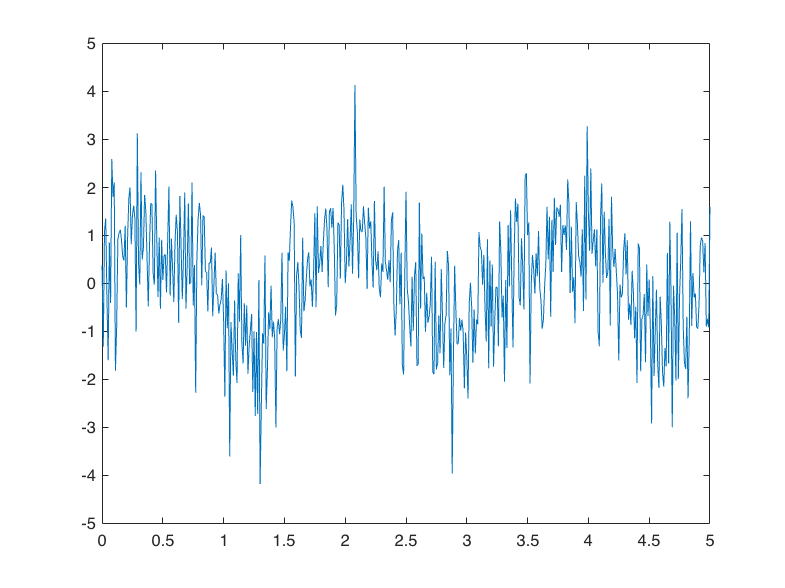

t = [0:0.01:5];
f = 0.6; %Hz
x = sin(2*pi*f*t);
y = x + randn(size(x));
plot(t,y);

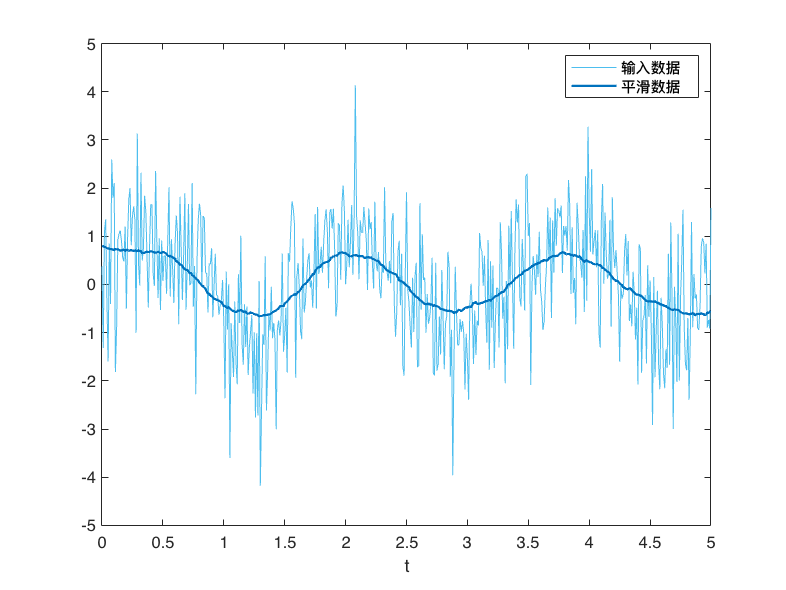

% 对输入数据进行平滑处理
smoothedData = smoothdata(y,"movmean","SmoothingFactor",0.89,"SamplePoints",t);

% 显示结果
clf
plot(t,y,"Color",[77 190 238]/255,"DisplayName","输入数据")
hold on
plot(t,smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","平滑数据")
hold off
legend
xlabel("t")